# Machine Learning: Programming Exercise 2 

## Logistic Regression

In this exercise, you will implement logistic regression and apply it to two different datasets.

### Files needed for this exercise

- `ex2.mlx` - MATLAB Live Script that steps you through the exercise

- ex2data1.txt - Training set for the first half of the exercise

- ex2data2.txt - Training set for the second half of the exercise

- `submit.m` - Submission script that sends your solutions to our servers

- `mapFeature.m` - Function to generate polynomial features

- `plotDecisionBoundary.m` - Function to plot classifier's decision boundary

- *`plotData.m` - Function to plot 2D classification data

- *`sigmoid.m` - Sigmoid function

- *`costFunction.m` - Logistic regression cost function

- *`predict.m` - Logistic regression prediction function

- `*costFunctionReg.m` - Regularized logistic regression cost function

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex2' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       costFunctionReg.m       ex2data1.txt            mapFeature.m            predict.m               token.mat               
..                      ex2.mlx                 ex2data2.txt            plotData.m              sigmoid.m               
costFunction.m          ex2_companion.mlx       lib                     plotDecisionBoundary.m  submit.m                



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Logistic Regression

In this part of the exercise, you will build a logistic regression model to predict whether a student gets admitted into a university. Suppose that you are the administrator of a university department and you want to determine each applicant's chance of admission based on their results on two exams. You have historical data from previous applicants that you can use as a training set for logistic regression. For each training example, you have the applicant's scores on two exams and the admissions decision.

    Your task is to build a classification model that estimates an applicant's probability of admission based the scores from those two exams. `ex2.mlx` will guide you through the exercise. To begin, run the code below to load the data into MATLAB.

% Load Data
% The first two columns contain the exam scores and the third column contains the label.
data = load('ex2data1.txt');
X = data(:, [1, 2]); 
y = data(:, 3);

### 1.1 Visualizing the data

Before starting to implement any learning algorithm, it is always good to visualize the data if possible. The code below will load the data and display it on a 2-dimensional plot by calling the function `plotData`. You will now complete the code in `plotData` so that it displays a figure like Figure 1, where the axes are the two exam scores, and the positive and negative examples are shown with different markers.

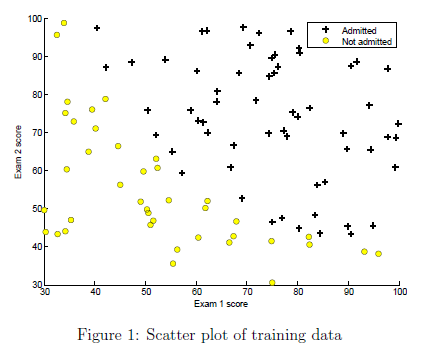

To help you get more familiar with plotting, we have left `plotData.m` empty so you can try to implement it yourself. However, this is an optional (ungraded) exercise. We also provide our implementation below so you can copy it or refer to it. If you choose to copy our example, make sure you learn what each of its commands is doing by consulting the MATLAB documentation.

Once you have added your own or the above code to `plotData.m`, run the code in this section to call the `plotData` function.

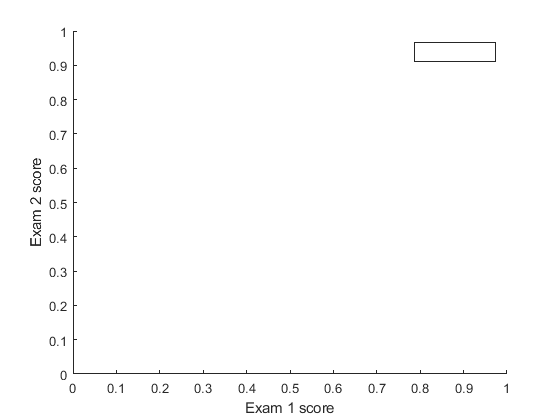

% Plot the data with + indicating (y = 1) examples and o indicating (y = 0) examples.
plotData(X, y);
 
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')

### 1.2 Implementation

#### 1.2.1 Warmup exercise: sigmoid function

Before you start with the actual cost function, recall that the logistic regression hypothesis is defined as:


$$ h_{\theta}(x) = g(\theta^Tx),$$


where function $g$ is the sigmoid function. The sigmoid function is defined as:


$$g(z) = \frac{1}{1+e^{-z}}$$


    Your first step is to implement this function in `sigmoid.m` so it can be called by the rest of your program. When you are finished, try testing a few values by calling `sigmoid(x)` in the code section below. For large positive values of `x`, the sigmoid should be close to 1, while for large negative values, the sigmoid should be close to 0. Evaluating `sigmoid(0)` should give you exactly 0.5. **Your code should also work with vectors and matrices**. For a matrix, your function should perform the sigmoid function on every element.

% Provide input values to the sigmoid function below and run to check your implementation
sigmoid(0)

ans = 0.5000

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.2.2 Cost function and gradient

Now you will implement the cost function and gradient for logistic regression. Complete the code in `costFunction.m` to return the cost and gradient. Recall that the cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


and the gradient of the cost is a vector of the same length as $\theta$ where the $j$th element (for $j = 0,\; 1,\ldots, n)$ is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}$$


Note that while this gradient looks identical to the linear regression gradient, the formula is actually different because linear and logistic regression have different definitions of $h_{\theta}(x)$. Once you are done, run the code sections below to set up your data and call your `costFunction` using the initial parameters of $\theta$. You should see that the cost is about 0.693 and gradients of about -0.1000,  -12.0092, and -11.2628.

#### Initialize the data

%  Setup the data matrix appropriately
[m, n] = size(X);

% Add intercept term to X
X = [ones(m, 1) X];

% Initialize the fitting parameters
initial_theta = zeros(n + 1, 1);

#### Compute the gradient

% Compute and display the initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);
fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


disp('Gradient at initial theta (zeros):'); 

Gradient at initial theta (zeros):


disp(grad);

    0.0085
    0.0085
    0.0188
    0.0001
    0.0503
    0.0115
    0.0377
    0.0184
    0.0073
    0.0082
    0.0235
    0.0393
    0.0022
    0.0129
    0.0031
    0.0393
    0.0200
    0.0043
    0.0034
    0.0058
    0.0045
    0.0310
    0.0310
    0.0011
    0.0063
    0.0004
    0.0073
    0.0014
    0.0388



#### 1.2.3 Learning parameters using `fminunc`

In the previous assignment, you found the optimal parameters of a linear regression model by implementing gradent descent. You wrote a cost function and calculated its gradient, then took a gradient descent step accordingly. This time, instead of taking gradient descent steps, you will use a MATLAB built-in function called `fminunc`. 

    MATLAB's `fminunc` is an optimization solver that finds the minimum of an unconstrained* function. For logistic regression, you want to optimize the cost function $J(\theta)$ with parameters. Concretely, you are going to use `fminunc` to find the best parameters $\theta$ for the logistic regression cost function, given a fixed dataset (of $X$ and $y$ values). You will pass to `fminunc` the following inputs:

- The initial values of the parameters we are trying to optimize.

- A function that, when given the training set and a particular $\theta$ computes the logistic regression cost and gradient with respect to $\theta$ for the dataset $(X, y)$

**Constraints in optimization often refer to constraints on the parameters, for example, constraints that bound the possible values *$\theta$* can take (e.g. *$\theta<1$*). Logistic regression does not have such constraints since *$\theta$* is allowed to take any real value.*

We already have code written below to call `fminunc` with the correct arguments:

- We first define the options to be used with `fminunc`. Specically, we set the `GradObj` option to `on`, which tells `fminunc` that our function returns both the cost and the gradient. This allows `fminunc` to use the gradient when minimizing the function. 

- Furthermore, we set the `MaxIter` option to 400, so that `fminunc` will run for at most 400 steps before it terminates. 

- To specify the actual function we are minimizing, we use a 'short-hand' for specifying functions with: `@(t)(costFunction(t,X,y))`. This creates a function, with argument `t`, which calls your `costFunction`. This allows us to wrap the `costFunction` for use with `fminunc`.

- If you have completed the `costFunction` correctly, `fminunc` will converge on the right optimization parameters and return the final values of the cost and $\theta$. Notice that by using `fminunc`, you did not have to write any loops yourself, or set a learning rate like you did for gradient descent. This is all done by `fminunc`: you only needed to provide a function calculating the cost and the gradient.

- Once `fminunc` completes, the remaining code will call your `costFunction` function using the optimal parameters of $\theta$. You should see that the cost is about 0.203. This final $\theta$ value will then be used to plot the decision boundary on the training data, resulting in a figure similar to Figure 2. We also encourage you to look at the code in `plotDecisionBoundary.m` to see how to plot such a boundary using the $\theta$ values.

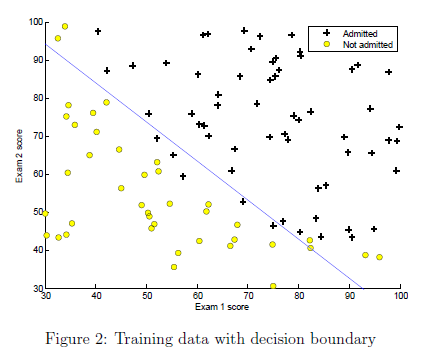

Run the code below and verify the results.

%  Set options for fminunc
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);

z =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


z =    -0.0645
   -0.0571
   -0.0569
   -0.0312
   -0.0321
   -0.0222
   -0.0171
   -0.0175
   -0.0227
   -0.0289


z =    -0.1371
   -0.0618
   -0.0597
    0.1720
    0.1510
    0.2181
    0.2591
    0.2379
    0.1763
    0.1049


z =     0.0774
    0.2073
    0.2038
    0.5885
    0.5251
    0.6139
    0.6880
    0.6340
    0.5241
    0.3855


z =     0.4210
    0.6007
    0.5758
    1.0982
    0.9487
    1.0326
    1.1557
    1.0524
    0.9014
    0.6774


z =     0.7928
    1.0054
    0.9411
    1.5544
    1.2767
    1.3239
    1.5108
    1.3482
    1.1783
    0.8635


z =     1.3018
    1.5350
    1.3972
    2.0682
    1.5719
    1.5318
    1.8199
    1.5693
    1.4067
    0.9697


z =     1.8046
    2.0322
    1.8043
    2.4600
    1.7112
    1.5482
    1.9467
    1.6055
    1.4870
    0.9381


z =     2.1759
    2.3741
    2.0675
    2.6413
    1.6829
    1.3983
    1.8831
    1.4761
    1.4278
    0.8129


z =     2.4108
    2.5658
    2.2007
    2.6512
    1.5462
    1.1577
    1.6980
    1.2550
    1.2919
    0.6586


z =     2.5202
    2.6282
    2.2299
    2.5432
    1.3616
    0.8973
    1.4620
    1.0119
    1.1368
    0.5271


z =     2.5214
    2.5908
    2.1862
    2.3799
    1.1902
    0.6856
    1.2466
    0.8133
    1.0150
    0.4582


z =     2.4499
    2.5022
    2.1150
    2.2415
    1.0963
    0.5887
    1.1268
    0.7224
    0.9724
    0.4755


z =     2.3637
    2.4247
    2.0669
    2.1903
    1.1062
    0.6182
    1.1304
    0.7506
    1.0169
    0.5634


z =     2.3086
    2.3997
    2.0723
    2.2372
    1.1981
    0.7296
    1.2250
    0.8548
    1.1211
    0.6874


z =     2.3043
    2.4435
    2.1439
    2.3673
    1.3366
    0.8636
    1.3574
    0.9764
    1.2503
    0.8179


z =     2.3526
    2.5695
    2.3008
    2.5882
    1.5136
    0.9873
    1.4974
    1.0750
    1.3857
    0.9405


z =     2.4166
    2.7197
    2.4782
    2.8022
    1.6385
    1.0117
    1.5490
    1.0600
    1.4283
    0.9586


z =     2.4313
    2.8036
    2.5856
    2.9113
    1.6659
    0.9349
    1.4889
    0.9339
    1.3471
    0.8530


z =     2.3863
    2.7989
    2.6029
    2.9101
    1.6305
    0.8311
    1.3800
    0.7822
    1.2083
    0.7008


z =     2.3219
    2.7526
    2.5771
    2.8626
    1.5916
    0.7629
    1.2910
    0.6735
    1.0859
    0.5748


z =     2.2565
    2.6973
    2.5454
    2.8085
    1.5724
    0.7336
    1.2286
    0.6009
    0.9790
    0.4676


z =     2.2185
    2.6664
    2.5404
    2.7834
    1.5971
    0.7598
    1.2142
    0.5792
    0.9055
    0.3916


z =     2.2470
    2.7014
    2.5924
    2.8257
    1.6712
    0.8365
    1.2634
    0.6195
    0.8998
    0.3765


z =     2.3287
    2.7911
    2.6874
    2.9186
    1.7619
    0.9202
    1.3412
    0.6834
    0.9395
    0.4001


z =     2.4184
    2.8898
    2.7848
    3.0136
    1.8321
    0.9749
    1.4041
    0.7292
    0.9795
    0.4226


z =     2.4992
    2.9796
    2.8712
    3.0938
    1.8797
    1.0054
    1.4482
    0.7551
    1.0047
    0.4291


z =     2.5871
    3.0776
    2.9641
    3.1753
    1.9170
    1.0275
    1.4920
    0.7763
    1.0220
    0.4196


z =     2.6843
    3.1870
    3.0655
    3.2590
    1.9387
    1.0481
    1.5510
    0.8066
    1.0343
    0.3870


z =     2.7622
    3.2790
    3.1464
    3.3201
    1.9201
    1.0744
    1.6449
    0.8691
    1.0440
    0.3209


z =     2.7412
    3.2709
    3.1272
    3.2969
    1.8244
    1.1166
    1.7866
    0.9934
    1.0579
    0.2273


z =     2.5586
    3.0940
    2.9468
    3.1525
    1.6674
    1.1749
    1.9377
    1.1626
    1.0852
    0.1591


z =     2.3410
    2.8744
    2.7354
    2.9955
    1.5647
    1.2223
    2.0100
    1.2739
    1.1136
    0.1643


z =     2.2400
    2.7713
    2.6440
    2.9301
    1.5534
    1.2404
    2.0053
    1.2926
    1.1239
    0.1982


z =     2.2214
    2.7519
    2.6304
    2.9208
    1.5668
    1.2421
    1.9878
    1.2821
    1.1258
    0.2203


z =     2.2184
    2.7482
    2.6298
    2.9197
    1.5767
    1.2405
    1.9747
    1.2723
    1.1282
    0.2369


z =     2.2160
    2.7443
    2.6307
    2.9158
    1.5894
    1.2344
    1.9504
    1.2544
    1.1374
    0.2745


z =     2.2161
    2.7417
    2.6319
    2.9032
    1.5882
    1.2202
    1.9237
    1.2362
    1.1582
    0.3318


z =     2.2219
    2.7436
    2.6322
    2.8740
    1.5484
    1.1922
    1.9062
    1.2277
    1.1978
    0.4077


z =     2.2343
    2.7526
    2.6293
    2.8384
    1.4661
    1.1602
    1.9220
    1.2447
    1.2403
    0.4549


z =     2.2442
    2.7617
    2.6240
    2.8201
    1.3980
    1.1440
    1.9563
    1.2719
    1.2583
    0.4469


z =     2.2450
    2.7636
    2.6195
    2.8154
    1.3699
    1.1438
    1.9802
    1.2878
    1.2554
    0.4208


z =     2.2415
    2.7612
    2.6128
    2.8136
    1.3539
    1.1492
    2.0002
    1.2990
    1.2474
    0.3935


z =     2.2308
    2.7524
    2.5989
    2.8128
    1.3378
    1.1668
    2.0325
    1.3127
    1.2293
    0.3491


z =     2.2063
    2.7313
    2.5713
    2.8183
    1.3285
    1.2141
    2.0895
    1.3272
    1.1918
    0.2775


z =     2.1528
    2.6865
    2.5209
    2.8442
    1.3502
    1.3314
    2.1923
    1.3346
    1.1151
    0.1648


z =     2.0602
    2.6127
    2.4494
    2.9168
    1.4525
    1.5607
    2.3460
    1.3120
    0.9875
    0.0277


z =     1.9590
    2.5403
    2.3963
    3.0407
    1.6546
    1.8547
    2.4904
    1.2410
    0.8485
   -0.0562


z =     1.9200
    2.5226
    2.4035
    3.1523
    1.8481
    2.0400
    2.5346
    1.1577
    0.7860
   -0.0226


z =     1.9363
    2.5407
    2.4315
    3.1804
    1.9067
    2.0587
    2.5092
    1.1281
    0.8008
    0.0452


z = 118×1
    1.9497
    2.5496
    2.4392
    3.1725
    1.8990
    2.0374
    2.4914
    1.1294
    0.8184
    0.0712


z = 118×1
    1.9527
    2.5503
    2.4389
    3.1653
    1.8910
    2.0284
    2.4856
    1.1310
    0.8226
    0.0763


z = 118×1
    1.9573
    2.5504
    2.4365
    3.1539
    1.8778
    2.0135
    2.4754
    1.1311
    0.8272
    0.0823


z = 118×1
    1.9614
    2.5491
    2.4325
    3.1375
    1.8595
    1.9951
    2.4616
    1.1289
    0.8291
    0.0869


z = 118×1
    1.9675
    2.5486
    2.4283
    3.1165
    1.8334
    1.9665
    2.4388
    1.1217
    0.8299
    0.0938


z = 118×1
    1.9727
    2.5518
    2.4302
    3.0968
    1.8029
    1.9330
    2.4109
    1.1092
    0.8268
    0.1017


z = 118×1
    1.9786
    2.5732
    2.4582
    3.1051
    1.7837
    1.9025
    2.3853
    1.0928
    0.8251
    0.1191


z = 118×1
    1.9785
    2.6340
    2.5482
    3.1948
    1.8187
    1.9180
    2.4012
    1.0880
    0.8312
    0.1503


z = 118×1
    1.9764
    2.7440
    2.7110
    3.4021
    1.9489
    2.0150
    2.4934
    1.1165
    0.8640
    0.2001


z = 118×1
    1.9737
    2.8426
    2.8588
    3.6155
    2.1125
    2.1522
    2.6207
    1.1688
    0.9070
    0.2395


z = 118×1
    1.9753
    2.8780
    2.9110
    3.7059
    2.1981
    2.2264
    2.6854
    1.2009
    0.9292
    0.2522


z = 118×1
    1.9744
    2.8794
    2.9144
    3.7167
    2.2140
    2.2449
    2.7005
    1.2105
    0.9310
    0.2494


z = 118×1
    1.9745
    2.8787
    2.9136
    3.7203
    2.2219
    2.2548
    2.7081
    1.2164
    0.9324
    0.2483


z = 118×1
    1.9755
    2.8776
    2.9121
    3.7259
    2.2364
    2.2746
    2.7230
    1.2283
    0.9347
    0.2458


z = 118×1
    1.9805
    2.8794
    2.9125
    3.7357
    2.2581
    2.3043
    2.7449
    1.2458
    0.9383
    0.2427


z = 118×1
    1.9963
    2.8919
    2.9222
    3.7579
    2.2959
    2.3559
    2.7820
    1.2736
    0.9423
    0.2363


z = 118×1
    2.0372
    2.9331
    2.9582
    3.8064
    2.3570
    2.4376
    2.8385
    1.3096
    0.9430
    0.2232


z = 118×1
    2.1231
    3.0322
    3.0491
    3.9008
    2.4424
    2.5492
    2.9110
    1.3406
    0.9300
    0.1974


z = 118×1
    2.2440
    3.1859
    3.1934
    4.0301
    2.5180
    2.6461
    2.9672
    1.3342
    0.8942
    0.1624


z = 118×1
    2.3280
    3.3053
    3.3061
    4.1223
    2.5326
    2.6703
    2.9779
    1.2904
    0.8548
    0.1376


z = 118×1
    2.3397
    3.3316
    3.3306
    4.1374
    2.5047
    2.6462
    2.9674
    1.2631
    0.8426
    0.1327


z = 118×1
    2.3326
    3.3260
    3.3255
    4.1302
    2.4906
    2.6321
    2.9602
    1.2572
    0.8436
    0.1355


z = 118×1
    2.3261
    3.3195
    3.3195
    4.1226
    2.4815
    2.6218
    2.9534
    1.2531
    0.8446
    0.1381


z = 118×1
    2.3101
    3.3028
    3.3041
    4.1028
    2.4603
    2.5967
    2.9350
    1.2428
    0.8466
    0.1442


z = 118×1
    2.2865
    3.2774
    3.2807
    4.0720
    2.4301
    2.5590
    2.9047
    1.2257
    0.8498
    0.1539


z = 118×1
    2.2456
    3.2331
    3.2402
    4.0181
    2.3806
    2.4943
    2.8480
    1.1931
    0.8573
    0.1735


z = 118×1
    2.1822
    3.1653
    3.1789
    3.9357
    2.3105
    2.3972
    2.7532
    1.1362
    0.8754
    0.2120


z = 118×1
    2.0907
    3.0708
    3.0953
    3.8221
    2.2250
    2.2667
    2.6036
    1.0408
    0.9207
    0.2896


z = 118×1
    1.9890
    2.9757
    3.0152
    3.7112
    2.1663
    2.1469
    2.4120
    0.9073
    1.0204
    0.4289


z = 118×1
    1.9344
    2.9467
    2.9997
    3.6826
    2.2130
    2.1393
    2.2527
    0.7790
    1.1992
    0.6262


z = 118×1
    1.9895
    3.0413
    3.0926
    3.7886
    2.3897
    2.3081
    2.2269
    0.7390
    1.4416
    0.8127


z = 118×1
    2.1180
    3.2037
    3.2366
    3.9484
    2.5510
    2.5067
    2.3240
    0.8014
    1.6268
    0.8913


z = 118×1
    2.1894
    3.2928
    3.3152
    4.0319
    2.5983
    2.5823
    2.4005
    0.8547
    1.6806
    0.8943


z = 118×1
    2.1988
    3.3068
    3.3276
    4.0470
    2.6034
    2.5971
    2.4199
    0.8679
    1.6918
    0.8961


z = 118×1
    2.1986
    3.3082
    3.3288
    4.0496
    2.6030
    2.5993
    2.4237
    0.8705
    1.6966
    0.8991


z = 118×1
    2.1951
    3.3076
    3.3283
    4.0507
    2.6002
    2.6004
    2.4264
    0.8722
    1.7061
    0.9062


z = 118×1
    2.1893
    3.3050
    3.3261
    4.0494
    2.5953
    2.5983
    2.4251
    0.8712
    1.7175
    0.9156


z = 118×1
    2.1778
    3.2988
    3.3209
    4.0439
    2.5851
    2.5915
    2.4180
    0.8662
    1.7361
    0.9313


z = 118×1
    2.1593
    3.2882
    3.3126
    4.0321
    2.5675
    2.5767
    2.4010
    0.8551
    1.7629
    0.9542


z = 118×1
    2.1291
    3.2710
    3.3007
    4.0092
    2.5367
    2.5497
    2.3672
    0.8342
    1.8013
    0.9866


z = 118×1
    2.0858
    3.2482
    3.2889
    3.9712
    2.4883
    2.5074
    2.3092
    0.8007
    1.8482
    1.0252


z = 118×1
    2.0370
    3.2293
    3.2902
    3.9209
    2.4255
    2.4598
    2.2297
    0.7593
    1.8845
    1.0516


z = 118×1
    2.0167
    3.2405
    3.3285
    3.8861
    2.3795
    2.4445
    2.1659
    0.7358
    1.8659
    1.0260


z = 118×1
    2.0638
    3.2995
    3.4047
    3.9087
    2.3973
    2.4976
    2.1794
    0.7618
    1.7711
    0.9337


z = 118×1
    2.1310
    3.3540
    3.4567
    3.9575
    2.4475
    2.5562
    2.2364
    0.8023
    1.6863
    0.8574


z = 118×1
    2.1591
    3.3711
    3.4687
    3.9789
    2.4714
    2.5760
    2.2659
    0.8185
    1.6559
    0.8325


z = 118×1
    2.1638
    3.3716
    3.4671
    3.9813
    2.4756
    2.5786
    2.2734
    0.8220
    1.6490
    0.8278


z = 118×1
    2.1627
    3.3691
    3.4642
    3.9787
    2.4740
    2.5770
    2.2731
    0.8221
    1.6485
    0.8279


z = 118×1
    2.1598
    3.3637
    3.4579
    3.9723
    2.4697
    2.5726
    2.2708
    0.8221
    1.6485
    0.8288


z = 118×1
    2.1559
    3.3566
    3.4497
    3.9633
    2.4634
    2.5659
    2.2666
    0.8218
    1.6490
    0.8305


z = 118×1
    2.1495
    3.3449
    3.4364
    3.9478
    2.4527
    2.5540
    2.2582
    0.8209
    1.6503
    0.8341


z = 118×1
    2.1409
    3.3284
    3.4176
    3.9246
    2.4373
    2.5357
    2.2434
    0.8183
    1.6523
    0.8410


z = 118×1
    2.1302
    3.3061
    3.3918
    3.8909
    2.4162
    2.5085
    2.2169
    0.8110
    1.6544
    0.8540


z = 118×1
    2.1214
    3.2823
    3.3629
    3.8493
    2.3940
    2.4752
    2.1724
    0.7916
    1.6533
    0.8776


z = 118×1
    2.1280
    3.2752
    3.3488
    3.8184
    2.3891
    2.4542
    2.1063
    0.7458
    1.6395
    0.9160


z = 118×1
    2.1757
    3.3261
    3.3922
    3.8523
    2.4440
    2.4958
    2.0420
    0.6636
    1.5976
    0.9611


z = 118×1
    2.2718
    3.4574
    3.5198
    3.9978
    2.5806
    2.6411
    2.0451
    0.5780
    1.5316
    0.9804


z = 118×1
    2.3570
    3.5883
    3.6519
    4.1666
    2.7131
    2.8024
    2.1211
    0.5481
    1.4831
    0.9615


z = 118×1
    2.3810
    3.6313
    3.6966
    4.2281
    2.7533
    2.8603
    2.1666
    0.5537
    1.4699
    0.9449


z = 118×1
    2.3814
    3.6339
    3.6997
    4.2328
    2.7538
    2.8653
    2.1745
    0.5579
    1.4698
    0.9417


z = 118×1
    2.3807
    3.6331
    3.6988
    4.2316
    2.7517
    2.8646
    2.1758
    0.5597
    1.4707
    0.9414


z = 118×1
    2.3794
    3.6310
    3.6962
    4.2284
    2.7471
    2.8626
    2.1775
    0.5629
    1.4727
    0.9416


z = 118×1
    2.3777
    3.6280
    3.6924
    4.2237
    2.7408
    2.8602
    2.1799
    0.5672
    1.4757
    0.9424


z = 118×1
    2.3750
    3.6225
    3.6852
    4.2159
    2.7306
    2.8570
    2.1841
    0.5746
    1.4807
    0.9442


z = 118×1
    2.3702
    3.6129
    3.6725
    4.2040
    2.7163
    2.8542
    2.1918
    0.5863
    1.4886
    0.9477


z = 118×1
    2.3602
    3.5940
    3.6488
    4.1865
    2.6980
    2.8548
    2.2067
    0.6058
    1.5010
    0.9536


z = 118×1
    2.3383
    3.5564
    3.6042
    4.1639
    2.6822
    2.8680
    2.2355
    0.6372
    1.5190
    0.9628


z = 118×1
    2.2921
    3.4844
    3.5246
    4.1436
    2.6905
    2.9144
    2.2891
    0.6845
    1.5407
    0.9746


z = 118×1
    2.2117
    3.3706
    3.4094
    4.1523
    2.7698
    3.0229
    2.3723
    0.7392
    1.5548
    0.9828


z = 118×1
    2.1216
    3.2585
    3.3124
    4.2259
    2.9509
    3.1837
    2.4556
    0.7677
    1.5407
    0.9755


z = 118×1
    2.0816
    3.2265
    3.3070
    4.3349
    3.1406
    3.3018
    2.4845
    0.7455
    1.5036
    0.9545


z = 118×1
    2.0852
    3.2447
    3.3387
    4.3805
    3.2049
    3.3245
    2.4718
    0.7165
    1.4841
    0.9437


z = 118×1
    2.0904
    3.2541
    3.3498
    4.3825
    3.2061
    3.3181
    2.4606
    0.7053
    1.4800
    0.9423


z = 118×1
    2.0913
    3.2553
    3.3505
    4.3791
    3.2022
    3.3146
    2.4565
    0.7021
    1.4792
    0.9422


z = 118×1
    2.0910
    3.2545
    3.3491
    4.3766
    3.2002
    3.3138
    2.4550
    0.7007
    1.4789
    0.9423


z = 118×1
    2.0901
    3.2527
    3.3464
    4.3735
    3.1984
    3.3140
    2.4536
    0.6991
    1.4787
    0.9425


z = 118×1
    2.0886
    3.2499
    3.3423
    4.3697
    3.1970
    3.3154
    2.4524
    0.6970
    1.4784
    0.9428


z = 118×1
    2.0862
    3.2450
    3.3353
    4.3641
    3.1956
    3.3190
    2.4511
    0.6938
    1.4782
    0.9434


z = 118×1
    2.0824
    3.2371
    3.3237
    4.3552
    3.1942
    3.3259
    2.4499
    0.6891
    1.4780
    0.9447


z = 118×1
    2.0770
    3.2240
    3.3041
    4.3397
    3.1925
    3.3387
    2.4493
    0.6824
    1.4785
    0.9475


z = 118×1
    2.0698
    3.2020
    3.2701
    4.3111
    3.1898
    3.3624
    2.4509
    0.6740
    1.4810
    0.9537


z = 118×1
    2.0628
    3.1654
    3.2107
    4.2556
    3.1844
    3.4058
    2.4591
    0.6665
    1.4892
    0.9676


z = 118×1
    2.0644
    3.1088
    3.1112
    4.1485
    3.1729
    3.4823
    2.4841
    0.6698
    1.5126
    0.9981


z = 118×1
    2.0958
    3.0412
    2.9738
    3.9669
    3.1497
    3.5963
    2.5404
    0.7058
    1.5679
    1.0565


z = 118×1
    2.1805
    3.0113
    2.8670
    3.7490
    3.1111
    3.6980
    2.6196
    0.7901
    1.6621
    1.1357


z = 118×1
    2.2938
    3.0569
    2.8718
    3.5957
    3.0539
    3.6949
    2.6662
    0.8871
    1.7586
    1.1963


z = 118×1
    2.3651
    3.1212
    2.9366
    3.5450
    2.9920
    3.6021
    2.6487
    0.9360
    1.8013
    1.2130


z = 118×1
    2.3839
    3.1492
    2.9712
    3.5479
    2.9654
    3.5489
    2.6264
    0.9424
    1.8010
    1.2095


z = 118×1
    2.3848
    3.1538
    2.9784
    3.5526
    2.9599
    3.5362
    2.6199
    0.9421
    1.7966
    1.2064


z = 118×1
    2.3835
    3.1533
    2.9786
    3.5537
    2.9590
    3.5340
    2.6187
    0.9421
    1.7946
    1.2055


z = 118×1
    2.3825
    3.1524
    2.9781
    3.5543
    2.9588
    3.5337
    2.6186
    0.9424
    1.7936
    1.2054


z = 118×1
    2.3810
    3.1511
    2.9770
    3.5554
    2.9591
    3.5339
    2.6191
    0.9429
    1.7925
    1.2057


z = 118×1
    2.3791
    3.1492
    2.9754
    3.5572
    2.9600
    3.5350
    2.6206
    0.9440
    1.7911
    1.2064


z = 118×1
    2.3765
    3.1464
    2.9725
    3.5602
    2.9622
    3.5377
    2.6238
    0.9458
    1.7893
    1.2080


z = 118×1
    2.3733
    3.1422
    2.9676
    3.5646
    2.9660
    3.5431
    2.6298
    0.9489
    1.7869
    1.2106


z = 118×1
    2.3701
    3.1359
    2.9585
    3.5705
    2.9722
    3.5528
    2.6408
    0.9543
    1.7839
    1.2148


z = 118×1
    2.3692
    3.1273
    2.9419
    3.5756
    2.9801
    3.5687
    2.6594
    0.9631
    1.7805
    1.2213


z = 118×1
    2.3775
    3.1178
    2.9118
    3.5723
    2.9851
    3.5912
    2.6879
    0.9767
    1.7786
    1.2307


z = 118×1
    2.4105
    3.1148
    2.8646
    3.5423
    2.9740
    3.6134
    2.7219
    0.9932
    1.7836
    1.2423


z = 118×1
    2.4818
    3.1343
    2.8153
    3.4693
    2.9295
    3.6152
    2.7380
    1.0007
    1.8027
    1.2506


z = 118×1
    2.5610
    3.1783
    2.8050
    3.3899
    2.8700
    3.5868
    2.7121
    0.9851
    1.8293
    1.2503


z = 118×1
    2.5967
    3.2107
    2.8260
    3.3524
    2.8346
    3.5532
    2.6719
    0.9645
    1.8447
    1.2478


z = 118×1
    2.5988
    3.2167
    2.8369
    3.3414
    2.8219
    3.5346
    2.6519
    0.9581
    1.8484
    1.2476


z = 118×1
    2.5968
    3.2158
    2.8380
    3.3402
    2.8200
    3.5313
    2.6488
    0.9579
    1.8486
    1.2482


z = 118×1
    2.5958
    3.2152
    2.8380
    3.3397
    2.8194
    3.5304
    2.6479
    0.9580
    1.8485
    1.2485


z = 118×1
    2.5948
    3.2145
    2.8378
    3.3390
    2.8182
    3.5291
    2.6468
    0.9582
    1.8483
    1.2493


z = 118×1
    2.5941
    3.2141
    2.8376
    3.3380
    2.8168
    3.5278
    2.6455
    0.9584
    1.8482
    1.2503


z = 118×1
    2.5935
    3.2138
    2.8375
    3.3364
    2.8144
    3.5257
    2.6433
    0.9586
    1.8483
    1.2522


z = 118×1
    2.5934
    3.2139
    2.8374
    3.3338
    2.8107
    3.5223
    2.6398
    0.9588
    1.8486
    1.2554


z = 118×1
    2.5943
    3.2149
    2.8375
    3.3288
    2.8045
    3.5164
    2.6334
    0.9591
    1.8496
    1.2609


z = 118×1
    2.5973
    3.2178
    2.8380
    3.3193
    2.7938
    3.5055
    2.6220
    0.9597
    1.8521
    1.2697


z = 118×1
    2.6050
    3.2247
    2.8394
    3.3002
    2.7748
    3.4843
    2.6008
    0.9611
    1.8576
    1.2835


z = 118×1
    2.6228
    3.2406
    2.8428
    3.2608
    2.7409
    3.4416
    2.5605
    0.9650
    1.8693
    1.3028


z = 118×1
    2.6612
    3.2752
    2.8512
    3.1831
    2.6822
    3.3578
    2.4868
    0.9748
    1.8927
    1.3234


z = 118×1
    2.7314
    3.3420
    2.8722
    3.0554
    2.5990
    3.2177
    2.3726
    0.9950
    1.9314
    1.3273


z = 118×1
    2.8176
    3.4362
    2.9163
    2.9301
    2.5340
    3.0668
    2.2609
    1.0217
    1.9704
    1.2848


z = 118×1
    2.8611
    3.5037
    2.9676
    2.9020
    2.5379
    3.0062
    2.2282
    1.0374
    1.9793
    1.2094


z = 118×1
    2.8497
    3.5042
    2.9773
    2.9184
    2.5602
    3.0123
    2.2449
    1.0394
    1.9700
    1.1640


z = 118×1
    2.8353
    3.4888
    2.9678
    2.9248
    2.5673
    3.0212
    2.2571
    1.0397
    1.9658
    1.1545


z = 118×1
    2.8311
    3.4833
    2.9637
    2.9266
    2.5687
    3.0243
    2.2609
    1.0398
    1.9649
    1.1540


z = 118×1
    2.8299
    3.4813
    2.9620
    2.9268
    2.5688
    3.0250
    2.2618
    1.0397
    1.9647
    1.1542


z = 118×1
    2.8289
    3.4796
    2.9605
    2.9269
    2.5688
    3.0253
    2.2622
    1.0395
    1.9646
    1.1545


z = 118×1
    2.8277
    3.4775
    2.9586
    2.9269
    2.5688
    3.0255
    2.2624
    1.0392
    1.9645
    1.1548


z = 118×1
    2.8261
    3.4747
    2.9560
    2.9267
    2.5689
    3.0256
    2.2623
    1.0387
    1.9644
    1.1551


z = 118×1
    2.8243
    3.4711
    2.9525
    2.9263
    2.5695
    3.0257
    2.2615
    1.0377
    1.9643
    1.1557


z = 118×1
    2.8225
    3.4668
    2.9480
    2.9254
    2.5707
    3.0259
    2.2596
    1.0358
    1.9643
    1.1567


z = 118×1
    2.8213
    3.4622
    2.9425
    2.9235
    2.5732
    3.0262
    2.2554
    1.0324
    1.9651
    1.1588


z = 118×1
    2.8224
    3.4589
    2.9365
    2.9193
    2.5778
    3.0267
    2.2473
    1.0261
    1.9677
    1.1636


z = 118×1
    2.8287
    3.4607
    2.9319
    2.9102
    2.5855
    3.0270
    2.2317
    1.0147
    1.9752
    1.1743


z = 118×1
    2.8461
    3.4759
    2.9338
    2.8905
    2.5969
    3.0258
    2.2032
    0.9941
    1.9943
    1.1983


z = 118×1
    2.8815
    3.5196
    2.9533
    2.8508
    2.6110
    3.0193
    2.1552
    0.9595
    2.0382
    1.2482


z = 118×1
    2.9311
    3.6035
    3.0054
    2.7876
    2.6207
    3.0006
    2.0925
    0.9138
    2.1193
    1.3329


z = 118×1
    2.9575
    3.6960
    3.0825
    2.7288
    2.6099
    2.9639
    2.0540
    0.8844
    2.2148
    1.4234


z = 118×1
    2.9284
    3.7344
    3.1414
    2.7043
    2.5672
    2.9108
    2.0687
    0.8945
    2.2722
    1.4677


z = 118×1
    2.8710
    3.7109
    3.1546
    2.7054
    2.5134
    2.8635
    2.1095
    0.9230
    2.2745
    1.4622


z = 118×1
    2.8384
    3.6776
    3.1404
    2.7130
    2.4871
    2.8494
    2.1359
    0.9370
    2.2528
    1.4445


z = 118×1
    2.8292
    3.6599
    3.1262
    2.7141
    2.4794
    2.8493
    2.1423
    0.9367
    2.2383
    1.4362


z = 118×1
    2.8281
    3.6550
    3.1203
    2.7119
    2.4778
    2.8498
    2.1403
    0.9328
    2.2346
    1.4352


z = 118×1
    2.8279
    3.6548
    3.1197
    2.7107
    2.4775
    2.8493
    2.1389
    0.9313
    2.2351
    1.4358


z = 118×1
    2.8279
    3.6550
    3.1199
    2.7103
    2.4772
    2.8488
    2.1385
    0.9309
    2.2356
    1.4361


z = 118×1
    2.8278
    3.6553
    3.1201
    2.7099
    2.4769
    2.8483
    2.1382
    0.9308
    2.2363
    1.4365


z = 118×1
    2.8278
    3.6559
    3.1206
    2.7092
    2.4762
    2.8472
    2.1377
    0.9306
    2.2376
    1.4372


z = 118×1
    2.8279
    3.6569
    3.1215
    2.7080
    2.4751
    2.8455
    2.1369
    0.9304
    2.2398
    1.4383


z = 118×1
    2.8282
    3.6587
    3.1229
    2.7063
    2.4734
    2.8426
    2.1355
    0.9302
    2.2435
    1.4402


z = 118×1
    2.8291
    3.6619
    3.1253
    2.7036
    2.4705
    2.8376
    2.1329
    0.9298
    2.2497
    1.4434


z = 118×1
    2.8311
    3.6677
    3.1293
    2.6996
    2.4660
    2.8290
    2.1282
    0.9290
    2.2599
    1.4487


z = 118×1
    2.8357
    3.6782
    3.1361
    2.6942
    2.4589
    2.8137
    2.1190
    0.9270
    2.2770
    1.4573


z = 118×1
    2.8465
    3.6979
    3.1474
    2.6882
    2.4483
    2.7857
    2.1006
    0.9225
    2.3048
    1.4711


z = 118×1
    2.8712
    3.7351
    3.1653
    2.6853
    2.4340
    2.7345
    2.0636
    0.9122
    2.3491
    1.4918


z = 118×1
    2.9251
    3.8032
    3.1915
    2.6981
    2.4201
    2.6451
    1.9926
    0.8901
    2.4121
    1.5183


z = 118×1
    3.0268
    3.9119
    3.2231
    2.7534
    2.4227
    2.5172
    1.8797
    0.8505
    2.4773
    1.5389


z = 118×1
    3.1640
    4.0344
    3.2501
    2.8695
    2.4677
    2.4144
    1.7688
    0.8023
    2.4906
    1.5280


z = 118×1
    3.2622
    4.1001
    3.2636
    2.9810
    2.5370
    2.4213
    1.7394
    0.7734
    2.4267
    1.4859


z = 118×1
    3.2726
    4.0871
    3.2535
    3.0185
    2.5766
    2.4792
    1.7652
    0.7675
    2.3579
    1.4525


z = 118×1
    3.2554
    4.0644
    3.2401
    3.0094
    2.5753
    2.4896
    1.7709
    0.7674
    2.3384
    1.4438


z = 118×1
    3.2454
    4.0541
    3.2346
    3.0048
    2.5736
    2.4907
    1.7719
    0.7677
    2.3339
    1.4414


z = 118×1
    3.2427
    4.0520
    3.2336
    3.0043
    2.5734
    2.4902
    1.7717
    0.7679
    2.3335
    1.4409


z = 118×1
    3.2419
    4.0516
    3.2335
    3.0044
    2.5735
    2.4899
    1.7715
    0.7680
    2.3336
    1.4408


z = 118×1
    3.2414
    4.0514
    3.2335
    3.0046
    2.5737
    2.4897
    1.7714
    0.7681
    2.3337
    1.4408


z = 118×1
    3.2408
    4.0512
    3.2334
    3.0049
    2.5740
    2.4894
    1.7715
    0.7684
    2.3340
    1.4407


z = 118×1
    3.2401
    4.0509
    3.2333
    3.0050
    2.5744
    2.4891
    1.7716
    0.7688
    2.3342
    1.4407


z = 118×1
    3.2392
    4.0506
    3.2330
    3.0051
    2.5748
    2.4888
    1.7720
    0.7695
    2.3346
    1.4405


z = 118×1
    3.2381
    4.0501
    3.2324
    3.0051
    2.5753
    2.4884
    1.7727
    0.7706
    2.3350
    1.4401


z = 118×1
    3.2367
    4.0495
    3.2314
    3.0047
    2.5760
    2.4878
    1.7741
    0.7723
    2.3355
    1.4395


z = 118×1
    3.2350
    4.0486
    3.2296
    3.0037
    2.5769
    2.4872
    1.7766
    0.7748
    2.3361
    1.4382


z = 118×1
    3.2327
    4.0473
    3.2265
    3.0018
    2.5782
    2.4868
    1.7806
    0.7784
    2.3367
    1.4358


z = 118×1
    3.2299
    4.0456
    3.2211
    2.9985
    2.5801
    2.4872
    1.7869
    0.7829
    2.3375
    1.4312


z = 118×1
    3.2265
    4.0430
    3.2117
    2.9932
    2.5834
    2.4903
    1.7963
    0.7871
    2.3388
    1.4226


z = 118×1
    3.2226
    4.0394
    3.1961
    2.9859
    2.5888
    2.5004
    1.8076
    0.7859
    2.3417
    1.4070


z = 118×1
    3.2191
    4.0347
    3.1734
    2.9782
    2.5966
    2.5250
    1.8150
    0.7676
    2.3489
    1.3826


z = 118×1
    3.2189
    4.0315
    3.1511
    2.9742
    2.6034
    2.5695
    1.8055
    0.7183
    2.3651
    1.3558


z = 118×1
    3.2248
    4.0339
    3.1464
    2.9767
    2.6055
    2.6234
    1.7765
    0.6514
    2.3891
    1.3465


z = 118×1
    3.2300
    4.0379
    3.1581
    2.9823
    2.6087
    2.6557
    1.7589
    0.6216
    2.4015
    1.3573


z = 118×1
    3.2292
    4.0385
    3.1652
    2.9871
    2.6091
    2.6530
    1.7559
    0.6251
    2.3970
    1.3618


z = 118×1
    3.2255
    4.0360
    3.1655
    2.9896
    2.6072
    2.6460
    1.7547
    0.6280
    2.3920
    1.3605


z = 118×1
    3.2242
    4.0350
    3.1649
    2.9906
    2.6074
    2.6451
    1.7547
    0.6280
    2.3910
    1.3596


z = 118×1
    3.2237
    4.0348
    3.1647
    2.9911
    2.6077
    2.6449
    1.7546
    0.6278
    2.3907
    1.3591


z = 118×1
    3.2233
    4.0346
    3.1645
    2.9916
    2.6080
    2.6447
    1.7544
    0.6276
    2.3905
    1.3586


z = 118×1
    3.2226
    4.0344
    3.1643
    2.9925
    2.6086
    2.6445
    1.7542
    0.6273
    2.3901
    1.3577


z = 118×1
    3.2215
    4.0340
    3.1638
    2.9937
    2.6095
    2.6443
    1.7540
    0.6268
    2.3896
    1.3565


z = 118×1
    3.2197
    4.0334
    3.1631
    2.9956
    2.6110
    2.6442
    1.7536
    0.6260
    2.3889
    1.3544


z = 118×1
    3.2169
    4.0323
    3.1619
    2.9983
    2.6132
    2.6441
    1.7530
    0.6246
    2.3877
    1.3513


z = 118×1
    3.2123
    4.0301
    3.1596
    3.0021
    2.6170
    2.6445
    1.7522
    0.6223
    2.3862
    1.3465


z = 118×1
    3.2045
    4.0256
    3.1549
    3.0070
    2.6234
    2.6462
    1.7508
    0.6181
    2.3844
    1.3394


z = 118×1
    3.1910
    4.0155
    3.1449
    3.0122
    2.6348
    2.6514
    1.7484
    0.6101
    2.3836
    1.3300


z = 118×1
    3.1667
    3.9924
    3.1230
    3.0143
    2.6558
    2.6656
    1.7442
    0.5946
    2.3880
    1.3202


z = 118×1
    3.1233
    3.9408
    3.0759
    3.0033
    2.6946
    2.7008
    1.7369
    0.5652
    2.4080
    1.3180


z = 118×1
    3.0532
    3.8392
    2.9870
    2.9601
    2.7599
    2.7760
    1.7273
    0.5163
    2.4641
    1.3441


z = 118×1
    2.9663
    3.6863
    2.8595
    2.8697
    2.8482
    2.9003
    1.7215
    0.4543
    2.5748
    1.4256


z = 118×1
    2.9113
    3.5494
    2.7539
    2.7659
    2.9298
    3.0322
    1.7205
    0.4021
    2.7207
    1.5587


z = 118×1
    2.9241
    3.5266
    2.7460
    2.7379
    2.9600
    3.0774
    1.7147
    0.3865
    2.8050
    1.6518


z = 118×1
    2.9309
    3.5424
    2.7631
    2.7512
    2.9505
    3.0592
    1.7102
    0.3953
    2.7995
    1.6533


z = 118×1
    2.9306
    3.5474
    2.7684
    2.7575
    2.9422
    3.0454
    1.7053
    0.3992
    2.7910
    1.6486


z = 118×1
    2.9281
    3.5450
    2.7666
    2.7573
    2.9429
    3.0474
    1.7071
    0.3997
    2.7908
    1.6482


z = 118×1
    2.9283
    3.5450
    2.7661
    2.7573
    2.9432
    3.0476
    1.7066
    0.3992
    2.7911
    1.6479


z = 118×1
    2.9282
    3.5449
    2.7660
    2.7572
    2.9432
    3.0476
    1.7065
    0.3992
    2.7912
    1.6479


z = 118×1
    2.9280
    3.5448
    2.7658
    2.7571
    2.9433
    3.0475
    1.7063
    0.3991
    2.7914
    1.6479


z = 118×1
    2.9277
    3.5446
    2.7657
    2.7571
    2.9435
    3.0475
    1.7062
    0.3990
    2.7916
    1.6478


z = 118×1
    2.9272
    3.5444
    2.7654
    2.7571
    2.9439
    3.0476
    1.7059
    0.3989
    2.7920
    1.6478


z = 118×1
    2.9262
    3.5439
    2.7650
    2.7572
    2.9444
    3.0476
    1.7056
    0.3988
    2.7927
    1.6478


z = 118×1
    2.9247
    3.5431
    2.7644
    2.7574
    2.9454
    3.0477
    1.7050
    0.3987
    2.7937
    1.6478


z = 118×1
    2.9223
    3.5418
    2.7634
    2.7578
    2.9470
    3.0477
    1.7042
    0.3985
    2.7954
    1.6478


z = 118×1
    2.9182
    3.5398
    2.7619
    2.7583
    2.9495
    3.0478
    1.7030
    0.3984
    2.7981
    1.6478


z = 118×1
    2.9115
    3.5365
    2.7595
    2.7588
    2.9532
    3.0477
    1.7013
    0.3982
    2.8021
    1.6476


z = 118×1
    2.9003
    3.5312
    2.7559
    2.7588
    2.9582
    3.0472
    1.6988
    0.3982
    2.8076
    1.6467


z = 118×1
    2.8819
    3.5229
    2.7507
    2.7565
    2.9640
    3.0452
    1.6957
    0.3987
    2.8139
    1.6440


z = 118×1
    2.8515
    3.5104
    2.7441
    2.7465
    2.9666
    3.0393
    1.6932
    0.4008
    2.8169
    1.6361


z = 118×1
    2.8038
    3.4938
    2.7386
    2.7160
    2.9541
    3.0243
    1.6950
    0.4067
    2.8039
    1.6153


z = 118×1
    2.7402
    3.4790
    2.7427
    2.6408
    2.8999
    2.9917
    1.7109
    0.4200
    2.7461
    1.5686


z = 118×1
    2.6901
    3.4829
    2.7714
    2.5089
    2.7802
    2.9437
    1.7525
    0.4395
    2.6163
    1.4927


z = 118×1
    2.7036
    3.5133
    2.8191
    2.3896
    2.6578
    2.9220
    1.8083
    0.4511
    2.4774
    1.4341


z = 118×1
    2.7542
    3.5383
    2.8478
    2.3545
    2.6182
    2.9419
    1.8438
    0.4502
    2.4256
    1.4310


z = 118×1
    2.7770
    3.5444
    2.8504
    2.3644
    2.6170
    2.9458
    1.8457
    0.4502
    2.4226
    1.4373


z = 118×1
    2.7795
    3.5431
    2.8477
    2.3695
    2.6194
    2.9451
    1.8435
    0.4503
    2.4261
    1.4401


z = 118×1
    2.7793
    3.5429
    2.8473
    2.3704
    2.6191
    2.9438
    1.8429
    0.4506
    2.4259
    1.4397


z = 118×1
    2.7792
    3.5428
    2.8471
    2.3705
    2.6190
    2.9435
    1.8428
    0.4506
    2.4258
    1.4396


z = 118×1
    2.7790
    3.5426
    2.8469
    2.3706
    2.6187
    2.9429
    1.8427
    0.4507
    2.4255
    1.4393


z = 118×1
    2.7789
    3.5425
    2.8467
    2.3706
    2.6181
    2.9419
    1.8427
    0.4508
    2.4250
    1.4387


z = 118×1
    2.7786
    3.5422
    2.8464
    2.3707
    2.6171
    2.9403
    1.8426
    0.4510
    2.4242
    1.4379


z = 118×1
    2.7782
    3.5419
    2.8459
    2.3708
    2.6155
    2.9378
    1.8425
    0.4514
    2.4230
    1.4364


z = 118×1
    2.7776
    3.5413
    2.8450
    2.3711
    2.6131
    2.9336
    1.8424
    0.4520
    2.4211
    1.4342


z = 118×1
    2.7765
    3.5402
    2.8436
    2.3715
    2.6092
    2.9269
    1.8423
    0.4531
    2.4181
    1.4307


z = 118×1
    2.7747
    3.5384
    2.8412
    2.3722
    2.6030
    2.9160
    1.8423
    0.4547
    2.4136
    1.4252


z = 118×1
    2.7714
    3.5350
    2.8369
    2.3730
    2.5927
    2.8981
    1.8423
    0.4570
    2.4067
    1.4166


z = 118×1
    2.7650
    3.5285
    2.8293
    2.3735
    2.5756
    2.8686
    1.8423
    0.4602
    2.3967
    1.4035


z = 118×1
    2.7524
    3.5152
    2.8149
    2.3724
    2.5465
    2.8203
    1.8424
    0.4635
    2.3830
    1.3844


z = 118×1
    2.7268
    3.4876
    2.7875
    2.3653
    2.4977
    2.7431
    1.8427
    0.4634
    2.3681
    1.3595


z = 118×1
    2.6768
    3.4329
    2.7374
    2.3437
    2.4223
    2.6333
    1.8436
    0.4499
    2.3646
    1.3375


z = 118×1
    2.5946
    3.3423
    2.6609
    2.2968
    2.3319
    2.5226
    1.8468
    0.4039
    2.4043
    1.3466


z = 118×1
    2.5086
    3.2469
    2.5877
    2.2260
    2.2744
    2.4980
    1.8542
    0.3209
    2.5124
    1.4194


z = 118×1
    2.4826
    3.2146
    2.5669
    2.1548
    2.2669
    2.5646
    1.8570
    0.2596
    2.6122
    1.5080


z = 118×1
    2.4969
    3.2240
    2.5761
    2.1105
    2.2687
    2.6117
    1.8519
    0.2505
    2.6255
    1.5379


z = 118×1
    2.5075
    3.2339
    2.5864
    2.0982
    2.2707
    2.6284
    1.8492
    0.2566
    2.6017
    1.5339


z = 118×1
    2.5094
    3.2368
    2.5901
    2.1001
    2.2710
    2.6291
    1.8485
    0.2593
    2.5876
    1.5274


z = 118×1
    2.5090
    3.2369
    2.5906
    2.1012
    2.2705
    2.6278
    1.8479
    0.2592
    2.5842
    1.5255


z = 118×1
    2.5088
    3.2368
    2.5906
    2.1016
    2.2704
    2.6271
    1.8473
    0.2586
    2.5838
    1.5252


z = 118×1
    2.5087
    3.2367
    2.5906
    2.1016
    2.2703
    2.6269
    1.8470
    0.2583
    2.5840
    1.5254


z = 118×1
    2.5087
    3.2366
    2.5905
    2.1015
    2.2704
    2.6269
    1.8467
    0.2578
    2.5844
    1.5257


z = 118×1
    2.5087
    3.2366
    2.5903
    2.1014
    2.2705
    2.6268
    1.8463
    0.2573
    2.5851
    1.5263


z = 118×1
    2.5087
    3.2365
    2.5901
    2.1012
    2.2706
    2.6268
    1.8458
    0.2565
    2.5863
    1.5271


z = 118×1
    2.5087
    3.2364
    2.5897
    2.1009
    2.2708
    2.6268
    1.8451
    0.2554
    2.5882
    1.5285


z = 118×1
    2.5089
    3.2363
    2.5890
    2.1005
    2.2710
    2.6267
    1.8443
    0.2538
    2.5912
    1.5305


z = 118×1
    2.5091
    3.2362
    2.5880
    2.0998
    2.2712
    2.6266
    1.8433
    0.2516
    2.5959
    1.5336


z = 118×1
    2.5095
    3.2363
    2.5865
    2.0986
    2.2712
    2.6263
    1.8423
    0.2487
    2.6032
    1.5381


z = 118×1
    2.5101
    3.2365
    2.5841
    2.0968
    2.2708
    2.6256
    1.8413
    0.2450
    2.6145
    1.5445


z = 118×1
    2.5108
    3.2372
    2.5806
    2.0938
    2.2697
    2.6239
    1.8403
    0.2403
    2.6317
    1.5531


z = 118×1
    2.5114
    3.2386
    2.5756
    2.0887
    2.2670
    2.6196
    1.8389
    0.2350
    2.6577
    1.5636


z = 118×1
    2.5109
    3.2414
    2.5694
    2.0800
    2.2615
    2.6091
    1.8343
    0.2295
    2.6963
    1.5727


z = 118×1
    2.5061
    3.2465
    2.5633
    2.0651
    2.2518
    2.5838
    1.8180
    0.2254
    2.7517
    1.5709


z = 118×1
    2.4904
    3.2543
    2.5620
    2.0401
    2.2382
    2.5282
    1.7688
    0.2253
    2.8261
    1.5356


z = 118×1
    2.4519
    3.2620
    2.5742
    1.9986
    2.2291
    2.4263
    1.6510
    0.2358
    2.9182
    1.4332


z = 118×1
    2.3786
    3.2579
    2.6094
    1.9382
    2.2535
    2.2947
    1.4385
    0.2686
    3.0168
    1.2477


z = 118×1
    2.3064
    3.2224
    2.6438
    1.9032
    2.3668
    2.2860
    1.2447
    0.3036
    3.0833
    1.1135


z = 118×1
    2.2153
    3.0830
    2.6083
    1.8767
    2.5842
    2.5201
    1.1443
    0.2781
    3.1394
    1.1349


z = 118×1
    2.2035
    3.1057
    2.6777
    1.9709
    2.5958
    2.4881
    1.1095
    0.2762
    3.0071
    1.1316


z = 118×1
    2.2333
    3.1455
    2.7094
    2.0254
    2.5732
    2.4541
    1.1199
    0.2730
    2.9302
    1.1181


z = 118×1
    2.2284
    3.1360
    2.7012
    2.0164
    2.5586
    2.4507
    1.1219
    0.2687
    2.9151
    1.1102


z = 118×1
    2.2297
    3.1374
    2.7020
    2.0135
    2.5549
    2.4493
    1.1213
    0.2698
    2.9125
    1.1040


z = 118×1
    2.2308
    3.1393
    2.7033
    2.0136
    2.5541
    2.4499
    1.1220
    0.2706
    2.9116
    1.1023


z = 118×1
    2.2312
    3.1399
    2.7037
    2.0134
    2.5541
    2.4502
    1.1221
    0.2709
    2.9118
    1.1024


z = 118×1
    2.2315
    3.1402
    2.7038
    2.0133
    2.5542
    2.4505
    1.1222
    0.2711
    2.9122
    1.1027


z = 118×1
    2.2318
    3.1405
    2.7038
    2.0132
    2.5545
    2.4509
    1.1222
    0.2712
    2.9126
    1.1032


z = 118×1
    2.2322
    3.1410
    2.7038
    2.0131
    2.5550
    2.4516
    1.1222
    0.2714
    2.9133
    1.1040


z = 118×1
    2.2330
    3.1417
    2.7038
    2.0129
    2.5559
    2.4525
    1.1221
    0.2717
    2.9143
    1.1052


z = 118×1
    2.2342
    3.1429
    2.7037
    2.0126
    2.5574
    2.4540
    1.1219
    0.2721
    2.9160
    1.1071


z = 118×1
    2.2363
    3.1448
    2.7037
    2.0123
    2.5599
    2.4564
    1.1217
    0.2728
    2.9188
    1.1101


z = 118×1
    2.2397
    3.1480
    2.7037
    2.0119
    2.5641
    2.4603
    1.1212
    0.2738
    2.9233
    1.1151


z = 118×1
    2.2453
    3.1533
    2.7037
    2.0113
    2.5710
    2.4669
    1.1205
    0.2752
    2.9309
    1.1231


z = 118×1
    2.2548
    3.1623
    2.7037
    2.0104
    2.5824
    2.4786
    1.1194
    0.2769
    2.9440
    1.1365


z = 118×1
    2.2712
    3.1778
    2.7034
    2.0086
    2.6018
    2.5002
    1.1177
    0.2777
    2.9674
    1.1595


z = 118×1
    2.2999
    3.2050
    2.7017
    2.0049
    2.6346
    2.5420
    1.1152
    0.2742
    3.0104
    1.1996


z = 118×1
    2.3510
    3.2538
    2.6966
    1.9965
    2.6897
    2.6256
    1.1116
    0.2556
    3.0905
    1.2698


z = 118×1
    2.4387
    3.3395
    2.6844
    1.9776
    2.7753
    2.7888
    1.1070
    0.1960
    3.2333
    1.3865


z = 118×1
    2.5701
    3.4737
    2.6633
    1.9376
    2.8783
    3.0632
    1.1038
    0.0556
    3.4484
    1.5451


z = 118×1
    2.7139
    3.6235
    2.6337
    1.8737
    2.9491
    3.3799
    1.1067
   -0.1643
    3.6960
    1.6952


z = 118×1
    2.8066
    3.6986
    2.5833
    1.8207
    2.9546
    3.5541
    1.1081
   -0.3595
    3.9109
    1.7958


z = 118×1
    2.7871
    3.6489
    2.5122
    1.7846
    2.8694
    3.4852
    1.1025
   -0.4242
    3.9887
    1.8161


z = 118×1
    2.7557
    3.5984
    2.4765
    1.7781
    2.8161
    3.3997
    1.1065
   -0.4082
    3.9787
    1.7989


z = 118×1
    2.7348
    3.5801
    2.4729
    1.7739
    2.7929
    3.3625
    1.1096
   -0.3919
    3.9512
    1.7759


z = 118×1
    2.7394
    3.5826
    2.4757
    1.7788
    2.7997
    3.3698
    1.1154
   -0.3866
    3.9444
    1.7734


z = 118×1
    2.7411
    3.5845
    2.4769
    1.7788
    2.8003
    3.3721
    1.1158
   -0.3871
    3.9406
    1.7718


z = 118×1
    2.7417
    3.5850
    2.4771
    1.7782
    2.7996
    3.3727
    1.1173
   -0.3868
    3.9370
    1.7698


z = 118×1
    2.7414
    3.5846
    2.4769
    1.7782
    2.7997
    3.3728
    1.1178
   -0.3863
    3.9350
    1.7686


z = 118×1
    2.7408
    3.5836
    2.4763
    1.7782
    2.8001
    3.3732
    1.1186
   -0.3860
    3.9337
    1.7678


z = 118×1
    2.7399
    3.5825
    2.4755
    1.7783
    2.8009
    3.3736
    1.1192
   -0.3855
    3.9333
    1.7676


z = 118×1
    2.7390
    3.5814
    2.4745
    1.7785
    2.8019
    3.3740
    1.1199
   -0.3850
    3.9341
    1.7681


z = 118×1
    2.7378
    3.5800
    2.4733
    1.7787
    2.8033
    3.3744
    1.1207
   -0.3843
    3.9363
    1.7696


z = 118×1
    2.7362
    3.5785
    2.4718
    1.7789
    2.8052
    3.3750
    1.1218
   -0.3830
    3.9406
    1.7725


z = 118×1
    2.7341
    3.5767
    2.4698
    1.7792
    2.8076
    3.3756
    1.1237
   -0.3808
    3.9482
    1.7776


z = 118×1
    2.7312
    3.5748
    2.4675
    1.7794
    2.8108
    3.3765
    1.1266
   -0.3771
    3.9609
    1.7861


z = 118×1
    2.7268
    3.5730
    2.4650
    1.7796
    2.8146
    3.3774
    1.1314
   -0.3709
    3.9815
    1.7999


z = 118×1
    2.7200
    3.5728
    2.4635
    1.7801
    2.8181
    3.3780
    1.1388
   -0.3609
    4.0147
    1.8219


z = 118×1
    2.7091
    3.5779
    2.4662
    1.7820
    2.8185
    3.3763
    1.1492
   -0.3454
    4.0674
    1.8564


z = 118×1
    2.6912
    3.5981
    2.4825
    1.7891
    2.8074
    3.3668
    1.1608
   -0.3235
    4.1498
    1.9088


z = 118×1
    2.6621
    3.6577
    2.5357
    1.8122
    2.7641
    3.3343
    1.1648
   -0.2985
    4.2731
    1.9839


z = 118×1
    2.6218
    3.8082
    2.6756
    1.8799
    2.6477
    3.2453
    1.1363
   -0.2852
    4.4360
    2.0755


z = 118×1
    2.5931
    4.1276
    2.9792
    2.0528
    2.4136
    3.0522
    1.0365
   -0.3143
    4.5897
    2.1500


z = 118×1
    2.6317
    4.6651
    3.5031
    2.4169
    2.0881
    2.7465
    0.8581
   -0.4053
    4.6204
    2.1518


z = 118×1
    2.7492
    5.2804
    4.1357
    2.9734
    1.8374
    2.4508
    0.6892
   -0.5217
    4.4473
    2.0595


z = 118×1
    2.8423
    5.5842
    4.4734
    3.3787
    1.8014
    2.3420
    0.6277
   -0.5898
    4.2783
    1.9742


z = 118×1
    2.8855
    5.6178
    4.5012
    3.4309
    1.8136
    2.3291
    0.6126
   -0.6105
    4.2705
    1.9719


z = 118×1
    2.9317
    5.6295
    4.4975
    3.4516
    1.8331
    2.3232
    0.6013
   -0.6261
    4.2699
    1.9711


z = 118×1
    2.9444
    5.6332
    4.4921
    3.4526
    1.8397
    2.3206
    0.5972
   -0.6308
    4.2737
    1.9733


z = 118×1
    2.9502
    5.6425
    4.4940
    3.4605
    1.8433
    2.3147
    0.5930
   -0.6374
    4.2821
    1.9773


z = 118×1
    2.9524
    5.6512
    4.4997
    3.4689
    1.8448
    2.3119
    0.5913
   -0.6420
    4.2893
    1.9807


z = 118×1
    2.9544
    5.6572
    4.5039
    3.4747
    1.8454
    2.3104
    0.5906
   -0.6449
    4.2950
    1.9832


z = 118×1
    2.9553
    5.6586
    4.5048
    3.4755
    1.8455
    2.3104
    0.5906
   -0.6453
    4.2964
    1.9838


z = 118×1
    2.9557
    5.6591
    4.5050
    3.4757
    1.8455
    2.3103
    0.5907
   -0.6453
    4.2968
    1.9840


z = 118×1
    2.9561
    5.6595
    4.5053
    3.4758
    1.8454
    2.3103
    0.5907
   -0.6453
    4.2970
    1.9841


z = 118×1
    2.9567
    5.6603
    4.5059
    3.4762
    1.8454
    2.3103
    0.5908
   -0.6452
    4.2972
    1.9842


z = 118×1
    2.9577
    5.6618
    4.5071
    3.4772
    1.8454
    2.3102
    0.5908
   -0.6451
    4.2974
    1.9844


z = 118×1
    2.9593
    5.6643
    4.5092
    3.4791
    1.8454
    2.3100
    0.5909
   -0.6450
    4.2976
    1.9845


z = 118×1
    2.9615
    5.6683
    4.5127
    3.4824
    1.8455
    2.3097
    0.5910
   -0.6448
    4.2978
    1.9847


z = 118×1
    2.9646
    5.6741
    4.5180
    3.4877
    1.8457
    2.3092
    0.5911
   -0.6446
    4.2978
    1.9848


z = 118×1
    2.9686
    5.6823
    4.5258
    3.4958
    1.8461
    2.3082
    0.5912
   -0.6445
    4.2977
    1.9848


z = 118×1
    2.9738
    5.6938
    4.5368
    3.5080
    1.8467
    2.3068
    0.5912
   -0.6443
    4.2972
    1.9844


z = 118×1
    2.9805
    5.7095
    4.5522
    3.5255
    1.8478
    2.3044
    0.5912
   -0.6441
    4.2961
    1.9833


z = 118×1
    2.9889
    5.7307
    4.5733
    3.5505
    1.8494
    2.3006
    0.5909
   -0.6438
    4.2937
    1.9808


z = 118×1
    2.9993
    5.7582
    4.6009
    3.5844
    1.8518
    2.2947
    0.5902
   -0.6435
    4.2891
    1.9753


z = 118×1
    3.0113
    5.7914
    4.6344
    3.6274
    1.8548
    2.2857
    0.5887
   -0.6430
    4.2805
    1.9650


z = 118×1
    3.0235
    5.8266
    4.6700
    3.6758
    1.8578
    2.2726
    0.5864
   -0.6426
    4.2658
    1.9471


z = 118×1
    3.0326
    5.8557
    4.6993
    3.7223
    1.8598
    2.2542
    0.5830
   -0.6434
    4.2423
    1.9192


z = 118×1
    3.0322
    5.8658
    4.7097
    3.7600
    1.8588
    2.2265
    0.5785
   -0.6491
    4.2040
    1.8771


z = 118×1
    3.0039
    5.8249
    4.6717
    3.7834
    1.8519
    2.1756
    0.5727
   -0.6692
    4.1320
    1.8072


z = 118×1
    2.8840
    5.6307
    4.4967
    3.7777
    1.8372
    2.0637
    0.5644
   -0.7233
    3.9773
    1.6753


z = 118×1
    2.5505
    5.1349
    4.0857
    3.7307
    1.8375
    1.8599
    0.5629
   -0.7784
    3.7027
    1.4624


z = 118×1
    2.1473
    4.6611
    3.7621
    3.8527
    1.8896
    1.6054
    0.5745
   -0.7562
    3.4344
    1.2882


z = 118×1
    2.0904
    4.7716
    3.9818
    4.5804
    2.0001
    1.2502
    0.5352
   -0.7397
    3.2263
    1.2277


z = 118×1
    2.0947
    5.1006
    4.4362
    5.6911
    2.3555
    1.1753
    0.5727
   -0.7126
    3.1564
    1.2955


z = 118×1
    2.2820
    5.6811
    5.0700
    6.8961
    2.6177
    1.0703
    0.5508
   -0.7589
    3.1765
    1.4311


z = 118×1
    2.3163
    6.0007
    5.4341
    7.9063
    3.0548
    1.2778
    0.6095
   -0.9041
    3.5066
    1.7528


z = 118×1
    2.2870
    6.1298
    5.6175
    8.2990
    3.1440
    1.3090
    0.6610
   -0.9083
    3.3807
    1.7376


z = 118×1
    2.2964
    6.0903
    5.5468
    8.2245
    3.1039
    1.2353
    0.6553
   -0.9156
    3.4301
    1.7674


z = 118×1
    2.1654
    5.8479
    5.3194
    8.0178
    3.0531
    1.1761
    0.6826
   -0.9198
    3.4850
    1.8321


z = 118×1
    2.1300
    5.7603
    5.2336
    7.9236
    3.0638
    1.2130
    0.6979
   -0.9289
    3.5418
    1.9015


z = 118×1
    2.1219
    5.7318
    5.2086
    7.8883
    3.0518
    1.2145
    0.6979
   -0.9394
    3.5716
    1.9498


z = 118×1
    2.1451
    5.7533
    5.2230
    7.8901
    3.0562
    1.2300
    0.6964
   -0.9459
    3.5832
    1.9651


z = 118×1
    2.1498
    5.7614
    5.2301
    7.9014
    3.0557
    1.2283
    0.6976
   -0.9466
    3.5751
    1.9589


z = 118×1
    2.1497
    5.7627
    5.2313
    7.9088
    3.0589
    1.2304
    0.6999
   -0.9471
    3.5699
    1.9538


z = 118×1
    2.1483
    5.7626
    5.2315
    7.9131
    3.0600
    1.2307
    0.7013
   -0.9477
    3.5679
    1.9523


z = 118×1
    2.1475
    5.7622
    5.2314
    7.9139
    3.0605
    1.2314
    0.7019
   -0.9483
    3.5680
    1.9526


z = 118×1
    2.1476
    5.7626
    5.2318
    7.9136
    3.0600
    1.2313
    0.7018
   -0.9485
    3.5685
    1.9532


z = 118×1
    2.1479
    5.7628
    5.2319
    7.9128
    3.0596
    1.2314
    0.7017
   -0.9485
    3.5688
    1.9535


z = 118×1
    2.1481
    5.7630
    5.2320
    7.9123
    3.0593
    1.2313
    0.7015
   -0.9484
    3.5689
    1.9535


z = 118×1
    2.1483
    5.7631
    5.2320
    7.9116
    3.0589
    1.2312
    0.7014
   -0.9483
    3.5690
    1.9535


z = 118×1
    2.1486
    5.7631
    5.2320
    7.9108
    3.0586
    1.2311
    0.7013
   -0.9482
    3.5691
    1.9534


z = 118×1
    2.1489
    5.7632
    5.2318
    7.9099
    3.0582
    1.2310
    0.7011
   -0.9481
    3.5692
    1.9533


z = 118×1
    2.1492
    5.7632
    5.2316
    7.9090
    3.0580
    1.2309
    0.7009
   -0.9479
    3.5692
    1.9531


z = 118×1
    2.1497
    5.7633
    5.2313
    7.9081
    3.0579
    1.2307
    0.7007
   -0.9477
    3.5693
    1.9527


z = 118×1
    2.1504
    5.7635
    5.2309
    7.9075
    3.0582
    1.2305
    0.7005
   -0.9474
    3.5693
    1.9523


z = 118×1
    2.1514
    5.7638
    5.2304
    7.9074
    3.0592
    1.2303
    0.7003
   -0.9472
    3.5694
    1.9519


z = 118×1
    2.1527
    5.7643
    5.2299
    7.9084
    3.0614
    1.2302
    0.7001
   -0.9469
    3.5693
    1.9514



Solver stopped prematurely.

fminunc stopped because it exceeded the iteration limit,
options.MaxIterations = 4.000000e+02.




% Print theta
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.224560


disp('theta:');disp(theta);

theta:
   1.0e+03 *

    0.0176
    0.0176
    0.0441
    0.0693
   -0.3445
   -0.1983
   -0.1844
   -0.2959
   -0.6223
   -0.5117
   -0.3288
    1.0955
    1.2703
    1.7590
    0.9021
    0.4373
    0.4712
    1.2370
    1.8254
    1.9336
    1.1343
    0.4648
   -1.1433
   -2.0222
   -3.4655
   -3.4894
   -3.2586
   -1.5502
   -0.5117



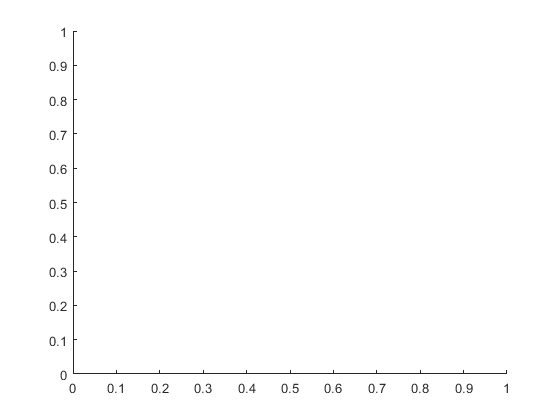

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in plotDecisionBoundary (line 37)
            z(i,j) = mapFeature(u(i), v(j))*theta;

Related documentation


% Plot Boundary
plotDecisionBoundary(theta, X, y);

% Add some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

#### 1.2.4 Evaluating logistic regression

After learning the parameters, you can use the model to predict whether a particular student will be admitted. For a student with an Exam 1 score of 45 and an Exam 2 score of 85, you should expect to see an admission probability of 0.776. Another way to evaluate the quality of the parameters we have found is to see how well the learned model predicts on our training set. In this part, your task is to complete the code in `predict.m`. The predict function will produce '1' or '0' predictions given a dataset and a learned parameter vector $\theta$.

    After you have completed the code in `predict.m`, the code below will proceed to report the training accuracy of your classifier by computing the percentage of examples it got correct. 

%  Predict probability for a student with score 45 on exam 1  and score 85 on exam 2 
prob = sigmoid([1 45 85] * theta);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Related documentation

fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);
% Compute accuracy on our training set
p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Regularized logistic regression

In this part of the exercise, you will implement regularized logistic regression to predict whether microchips from a fabrication plant passes quality assurance (QA). During QA, each microchip goes through various tests to ensure it is functioning correctly. Suppose you are the product manager of the factory and you have the test results for some microchips on two different tests. From these two tests, you would like to determine whether the microchips should be accepted or rejected. To help you make the decision, you have a dataset of test results on past microchips, from which you can build a logistic regression model.

### 2.1 Visualizing the data

Similar to the previous parts of this exercise, `plotData` is used in the code below to generate a figure like Figure 3, where the axes are the two test scores, and the positive ($y=1,$  accepted) and negative ($y=0,$ rejected) examples are shown with different markers. 

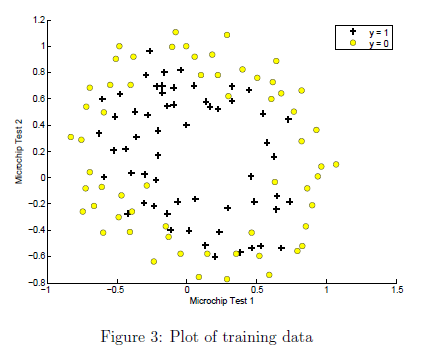

Run the code below and confirm you plot matches Figure 3.

%  The first two columns contains the X values and the third column
%  contains the label (y).
data = load('ex2data2.txt');
X = data(:, [1, 2]); y = data(:, 3);

plotData(X, y);
% Put some labels 
hold on;
% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')
% Specified in plot order
legend('y = 1', 'y = 0')

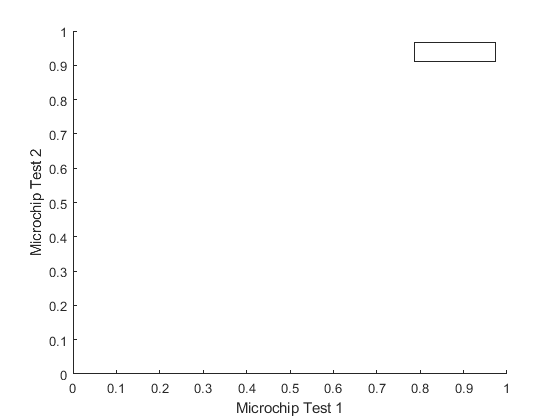

hold off;

        Figure 3 shows that our dataset cannot be separated into positive and negative examples by a straight-line through the plot. Therefore, a straightforward application of logistic regression will not perform well on this dataset since logistic regression will only be able to find a linear decision boundary.

### 2.2 Feature mapping

One way to fit the data better is to create more features from each data point. In the provided function `mapFeature.m`, we will map the features into all polynomial terms of $x_1$ and $x_2$ up to the sixth power.


$$\mathrm{mapFeature}\left(x\right)=\left\lbrack \begin{array}{c}
1\\
x_1 \\
x_2 \\
x_1^2 \\
x_1 x_2 \\
x_2^2 \\
x_1^3 \\
\vdots \;\\
x_1 x_2^5 \\
x_2^6 
\end{array}\right\rbrack$$


    As a result of this mapping, our vector of two features (the scores on two QA tests) has been transformed into a 28-dimensional vector. A logistic regression classifier trained on this higher-dimension feature vector will have a more complex decision boundary and will appear nonlinear when drawn in our 2-dimensional plot. 

    Run the code below to map the features.

% Add Polynomial Features
% Note that mapFeature also adds a column of ones for us, so the intercept term is handled
X = mapFeature(X(:,1), X(:,2));

    While the feature mapping allows us to build a more expressive classifier, it also more susceptible to overfitting. In the next parts of the exercise, you will implement regularized logistic regression to fit the data and also see for yourself how regularization can help combat the overfitting problem.

### 2.3 Cost function and gradient

Now you will implement code to compute the cost function and gradient for regularized logistic regression. Complete the code in `costFunctionReg.m` to return the cost and gradient. Recall that the regularized cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[
-y^{(i)} \log(h_{\theta}(x^{(i)}))-(1-y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2},$$


Note that you should not regularize the parameter $\theta_0$. In MATLAB, recall that indexing starts from 1, hence, you should not be regularizing the `theta(1)` parameter (which corresponds to $\theta_0$) in the code. The gradient of the cost function is a vector where the $j\mathrm{th}$ element is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1,$$


Once you are done, run the code below to call your `costFunctionReg` function using the initial value of $\theta$ (initialized to all zeros). You should see that the cost is about 0.693.

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Compute and display initial cost and gradient for regularized logistic regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);

ret = 0

fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.3.1 Learning parameters using `fminunc`

Similar to the previous parts, the next step is to use `fminunc` to learn the optimal parameters. If you have completed the cost and gradient for regularized logistic regression (`costFunctionReg.m`) correctly, you should be able to run the code in the following sections to learn the parameters using `fminunc` for multiple values of $\lambda$.

### 2.4 Plotting the decision boundary

To help you visualize the model learned by this classifier, we have provided the function `plotDecisionBoundary.m` which plots the (nonlinear) decision boundary that separates the positive and negative examples. In `plotDecisionBoundary.m`, we plot the nonlinear decision boundary by computing the classifier's predictions on an evenly spaced grid and then drew a contour plot of where the predictions change from $y = 0$ to $y = 1$. After learning the parameters, the code in the next section will plot a decision boundary similar to Figure 4.

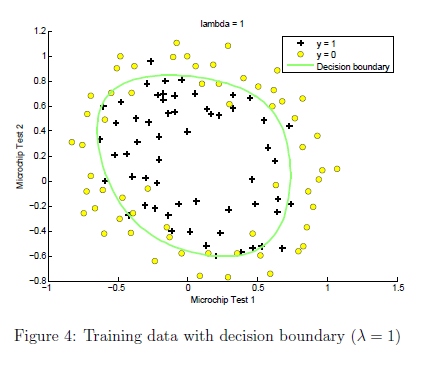

### 2.5 Optional (ungraded) exercises

In this part of the exercise, you will get to try out different regularization parameters for the dataset to understand how regularization prevents overfitting. Notice the changes in the decision boundary as you vary $\lambda$. With a small $\lambda$, you should find that the classifier gets almost every training example correct, but draws a very complicated boundary, thus overfitting the data (Figure 5). 

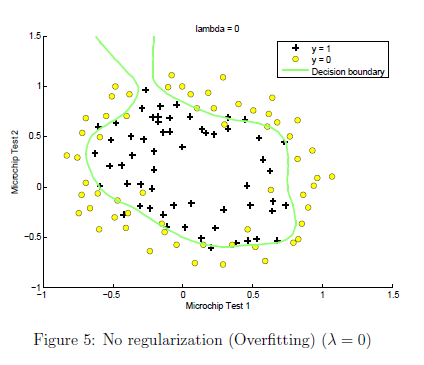

    This is not a good decision boundary: for example, it predicts that a point at $x = (0.25, 1.5)$ is accepted $(y = 1)$, which seems to be an incorrect decision given the training set. With a larger $\lambda$, you should see a plot that shows an simpler decision boundary which still separates the positives and negatives fairly well. However, if $\lambda$ is set to too high a value, you will not get a good fit and the decision boundary will not follow the data so well, thus underfitting the data (Figure 6).

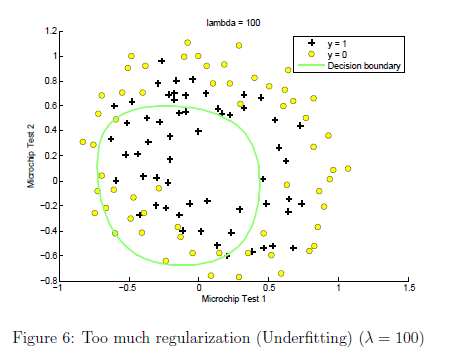

Use the control below to try the following values of $\lambda$: 0, 1, 10, 100. 

- How does the decision boundary change when you vary $\lambda$? 

- How does the training set accuracy vary?

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

lambda = 0;
% Set Options
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>


% Plot Boundary
plotDecisionBoundary(theta, X, y);

hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')

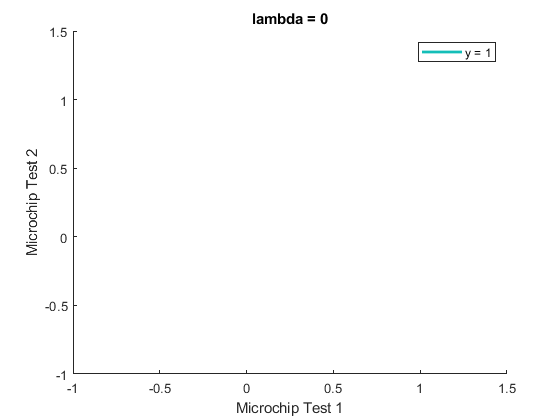

hold off;


% Compute accuracy on our training set
p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 0.000000


*You do not need to submit any solutions for these optional (ungraded) exercises.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the `submit` function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

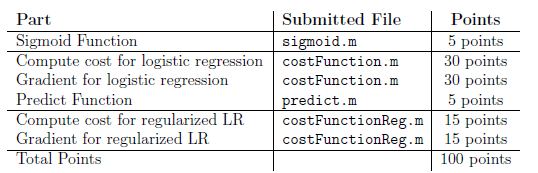

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.